# Modeling & Simulating Hourly Electricity

This example demonstrates fitting a non-linear regression tree model to hourly day-ahead electricity prices in the New England pool region. The log electricity prices are modeled with two additive components: a deterministic and stochastic component. The deterministic component takes into account observed electricity price changes due to changes in fuel (natural gas) prices, the daily temperature, the hour of the day, day of the week and holidays. This is modeled using a regression tree. The stochastic component is modeled as a seasonal AR process with heavy tailed innovations. 

Note: Regression trees are known to be weak learners which can very easily overfit the data. While we do not address this issue in this demo, you may want to use out-of-sample cross-validation to prune the tree to balance accuracy of a training and test set. This can be done manually by using a separate subset of the data to build the model and a different subset to test its accuracy or by using a function such as CROSSVAL in Statistics Toolbox

## Import Data

Data is loaded from a previously created MAT-file. The series consist of a vector of serial dates and the corresponding historical recorded temperature. 

clear
load Data\ngPrices.mat
load Data\elecPrices
tail(ngPrices)

ans = 8×5 timetable
            Time            RNGWHHDd    RNGC1d    RNGC2d    RNGC3d    RNGC4d
    ____________________    ________    ______    ______    ______    ______

    04-Jan-2019 00:00:00       2.8      3.044     2.905     2.688      2.66 
    07-Jan-2019 00:00:00      2.74      2.944     2.847     2.677     2.662 
    08-Jan-2019 00:00:00      2.89      2.967     2.835     2.695     2.683 
    09-Jan-2019 00:00:00      2.92      2.984      2.84     2.706     2.696 
    10-Jan-2019 00:00:00      2.95      2.969     2.813     2.706     2.698 
    11-Jan-2019 00:00:00      2.95      3.099     2.945     2.769     2.747 
    14-Jan-2019 00:00:00      3.36      

tail(elecPrices)

ans = 8×16 timetable
       Date       Hr_End    DA_Demand    RT_Demand    DA_LMP    DA_EC    DA_CC    DA_MLC    RT_LMP    RT_EC    RT_CC    RT_MLC    Dry_Bulb    Dew_Point    System_Load    Reg_Capacity_Price    Reg_Service_Price
    __________    ______    _________    _________    ______    _____    _____    ______    ______    _____    _____    ______    ________    _________    ___________    __________________    ________

vars2keep = {'Hr_End','DA_LMP','Dry_Bulb'}

vars2keep = 1×3 cell array
    {'Hr_End'}    {'DA_LMP'}    {'Dry_Bulb'}


T = elecPrices(:,vars2keep);
tail(T)

ans = 8×3 timetable
       Date       Hr_End    DA_LMP    Dry_Bulb
    __________    ______    ______    ________

    11/30/2018      17       79.9        36   
    11/30/2018      18       90.3        35   
    11/30/2018      19      78.27        35   
    11/30/2018      20      63.14        35   
    11/30/2018      21      61.17        35   
    11/30/2018      22       53.4        34   
    11/30/2018      23      46.71        34   
    11/30/2018      24      46.81        33   


There are 13 days with 0 local marginal pricing of electricity, this is the daylights savings time change effect on the data.  We fill these with the prior hours price.

daylightIndx = T.DA_LMP == 0;
sum(daylightIndx)

ans = 13

T.DA_LMP(daylightIndx) = T.DA_LMP(find(daylightIndx)-1);

Also import a list of local holidays that span the dataset. One can also use Financial Toolbox functions like HOLIDAYS, ISBUSDAY etc. to automatically generate holidays within the time range.  We use holidays for the date range in our date set.

hdays = holidays(min(T.Date),max(T.Date));
disp('Sample Holidays'); disp(hdays(1:20))

Sample Holidays
   1/17/2011 
   2/21/2011 
   4/22/2011 
   5/30/2011 
   7/4/2011  
   9/5/2011  
   11/24/2011
   12/26/2011
   1/2/2012  
   1/16/2012 
   2/20/2012 
   4/6/2012  
   5/28/2012 
   7/4/2012  
   9/3/2012  
   10/29/2012
   10/30/2012
   11/22/2012
   12/25/2012
   1/1/2013  



## Plot Prices

Create a visualization of the electricity prices from a macro and micro perspective

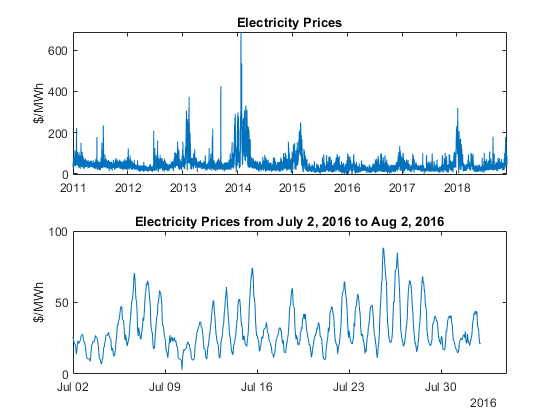

subplot(2,1,1);
plot(T.Date, T.DA_LMP);
ylabel('$/MWh'); title('Electricity Prices');
subplot(2,1,2);
dateind = timerange('July 2, 2016','Aug 2, 2016');
plot(T.Date(dateind), T.DA_LMP(dateind))
ylabel('$/MWh'); title('Electricity Prices from July 2, 2016 to Aug 2, 2016');

## Create Predictor and Response `timetable`

The deterministic component of the model will take into account the relationship between electricity prices and natural gas prices, temperatures, hour of the day, day of the week and holidays. Therefore we generate a matrix of these predictors for every observation. These predictors include,

- Temperature & Deviation from seasonal average (the stochastic component of temperature)

- Hour of day, Day of Week, Month of year

- Category variable for workday or hoiday/weekend

- NG spot price, previous day price and previous week price

% Temperature and deviation
tempModel = load('SavedModels\TemperatureModel.mat');
T.AveTemp = tempModel.m + tempModel.sinmodel(datenum(T.Date));
T.TempDeviation = T.Dry_Bulb - T.AveTemp;

% Hour of day is Hr_End, Month, and Calculate Day of Week and save as catgorical
T.Month = month(T.Date);
[~,T.WeekDay] = weekday(T.Date);
T.WeekDay = categorical(string(T.WeekDay));
T.WorkingDay = categorical(isbusday(T.Date,hdays),[1 0],{'Workday','Weekend/Holiday'});

% Spot fuel and prior spot fuel prices (syncronizing)
Pfuel = ngPrices(:,'RNGWHHDd');
Pfuel.Properties.VariableNames = {'Png'};

% keep consistent time with T
startTime = min(T.Date);
endTime = max(T.Date);
timeIdx = timerange(startTime,endTime,'closed');
Pfuel = Pfuel(timeIdx,:);

% retime to hourly with prieious pricing
Pfuel = retime(Pfuel,'hourly','linear');
PriorDay = lag(Pfuel);
PriorWk = lag(Pfuel,days(7));
Pfuel = synchronize(Pfuel,PriorDay);
Pfuel = synchronize(Pfuel,PriorWk);

% Join T and Pfuel and retime to hourly basis
T = synchronize(T,Pfuel);
tail(T)

ans = 8×11 timetable
       Date       Hr_End    DA_LMP    Dry_Bulb    AveTemp    TempDeviation    Month    WeekDay    WorkingDay    Png_Pfuel    Png_PriorDay    Png
    __________    ______    ______    ________    _______    _____________    _____    _______    __________    _________    ____________    ___

    11/30/2018      17       79.9        36       34.155          1.8451       11        Fri       Workday         NaN           NaN         NaN
    11/30/2018      18       90.3        35       34.142          0.8577       11        Fri       Wo

## Build Regression Tree Model

Build a regression tree to model electricity prices given predictors. Visualize a highly-pruned small subset of the tree.

Note: Regression trees can easily overfit a training set. See the text at the start of this example for more information on how to avoid these pitfalls.

X = timetable2table(T); % regressionLearner perfers to have tables.
X.NumericDate = datenum(X.Date); % add the date as a numeric value

% remove the missing year of data (2016)
X = rmmissing(X);

% Use this command to open the regression learner app and train a coarse
% tree:
% regressionLearner

% this is the model saved by generating code from the app:
[trainedModel, validationRMSE] = trainRegressionModel(X)

trainedModel = struct with fields:
           predictFcn: @(x)treePredictFcn(predictorExtractionFcn(x))
    RequiredVariables: {'Hr_End'  'Dry_Bulb'  'TempDeviation'  'Month'  'WeekDay'  'WorkingDay'  'Png_Pfuel'  'Png_PriorDay'  'Png'}
       RegressionTree: [1×1 RegressionTree]
                About: 'This struct is a trained model exported from Regression Learner R2018b.'
         HowToPredict: 'To make predictions on a new table, T, use: ↵  yfit = c.predictFcn(T) ↵replacing 'c' with the name of the variable that is this struct, e.g. 'trainedModel'. ↵ ↵The table, T, must contain the variables returned by: ↵  c.RequiredVariables ↵Variable formats (e.g. matrix/vector, datatype) must match the original training data. ↵Additional variables are ignored. ↵ ↵For more information, see How to predict using an exported model.'


validationRMSE = 18.1094

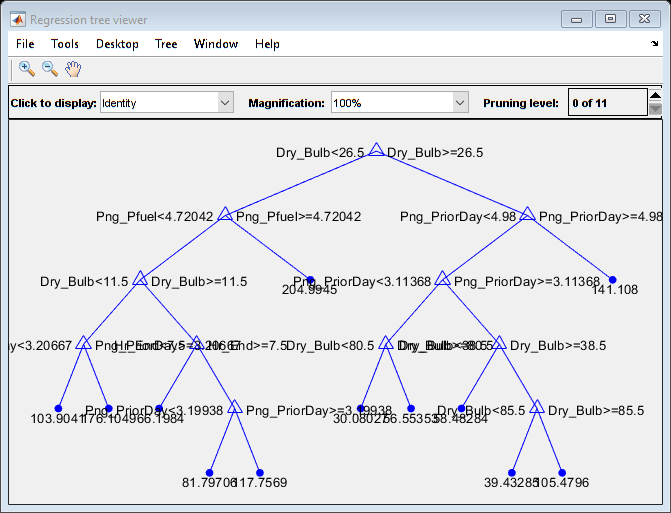

figure
subsettree = prune(trainedModel.RegressionTree,'level',1050);
view(subsettree,'Mode','graph')

## Compute & Visualize Model Performance

Predict electricity prices using the model and compare them with the observed prices. The visualization function here is the same function used in the comparison of predicted and actual values for the Temperature model. The mean absolute error (MAE) is also displayed.

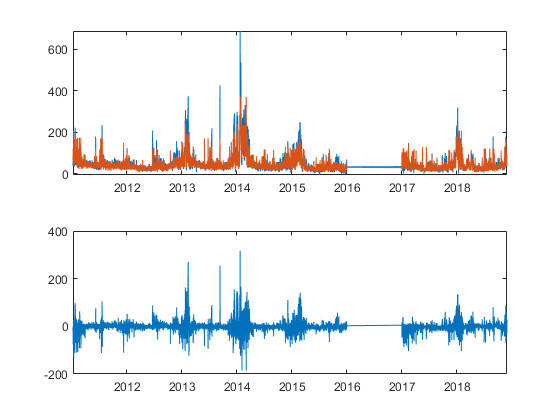

X.pred = trainedModel.predictFcn(X);
res = X.DA_LMP - X.pred;

subplot(2,1,1)
plot(X.Date, [X.DA_LMP X.pred])
subplot(2,1,2)
plot(X.Date, res)

disp(['Mean Absolute Error (in original units): $' num2str(mean(abs(res)))]);

Mean Absolute Error (in original units): $8.4779


disp(['Mean Absolute Percent Error (in original units): ' num2str(mean(abs(res./X.DA_LMP*100))) '%']);

Mean Absolute Percent Error (in original units): Inf%


## Analyze Serial Correlation in Residuals

The residuals, though fairly detrended may still have some serial correlation. This can be tested with autocorrelation plots

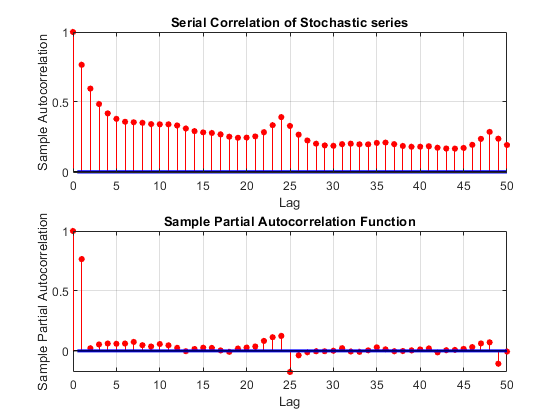

figure;
subplot(2,1,1)
autocorr(res,50);
title('Serial Correlation of Stochastic series');
subplot(2,1,2)
parcorr(res,50)

## Modeling the Stochastic Component with a seasonal AR model

One could choose to model the random component a mean reverting drift SDE. However, because of the seasonality, we will use an auto-regressive model with seasonal lags. As can be seen from the above plot, there is a strong seasonal correlation on an hourly and daily scale. Therefore we use lags at 1-4 hours and 1-2 days

lags = [1 2 3 4 23 24 25 48];
%% Estimate an ARIMAX Model of time series 
ARIMAX_ElecPrices = arima('Constant',NaN,'ARLags',lags,'D',0,'MALags',[],'Distribution','Gaussian');
validIndices = find(~any(isnan([X.DA_LMP,X.pred]),2));
preSampleNumber = ARIMAX_ElecPrices.P;
preSampleResponse = X.DA_LMP(validIndices(1:preSampleNumber));
estimateResponse = X.DA_LMP(validIndices(preSampleNumber+1:end));
pred = X.pred(validIndices);
ARIMAX_ElecPrices = estimate(ARIMAX_ElecPrices,estimateResponse,'Y0',preSampleResponse,'X',X.pred,'Display','off');
summarize(ARIMAX_ElecPrices)

 
   ARIMAX(48,0,0) Model (Gaussian Distribution)
 
    Effective Sample Size: 60313
    Number of Estimated Parameters: 11
    LogLikelihood: -198430
    AIC: 396883
    BIC: 396982
 
                  Value       StandardError    TStatistic      PValue   
                __________    _____________    __________    ___________

    Constant       -0.3307        0.04963       -6.6633       2.6776e-11
    AR{1}          0.98789      0.0011186        883.13                0
    AR{2}         -0.15461      0.0016413       -94.198                0
    AR{3}       0.00017018      0.0017575       0.09683          0.92286
    AR{4}        0.0030077      0.0012049        2.4962         0.012552
    AR{23}         0.12462      0.0011472       

## Analyze Residuals of Regression for Serial Correlation

The residuals from the regression should now be mostly serially uncorrelated. 

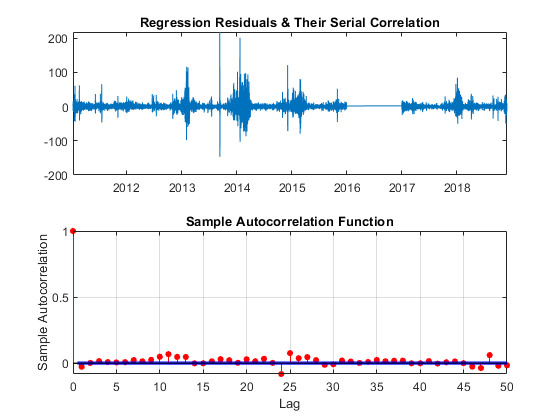

res = infer(ARIMAX_ElecPrices,estimateResponse,'Y0',preSampleResponse,'X',pred);
figure;
subplot(2,1,1);
dates = X.Date(validIndices);
plot(dates(preSampleNumber+1:end), res);
title('Regression Residuals & Their Serial Correlation');
subplot(2,1,2);
autocorr(res,50);

## Summary of model

The electricity model can now be defined by,

- The regression tree "model"

- Regression parameters "beta"

- Autocorrelation lags "lags"

- The residual probability distribution "PD"

- Optional presample data (the last observations of temperature for regression)

elecModel = struct('treemodel', trainedModel, 'reglags', lags, 'arimax', ARIMAX_ElecPrices,'lastDate',T.Date(end),'Freq','hourly')

elecModel = struct with fields:
    treemodel: [1×1 struct]
      reglags: [1 2 3 4 23 24 25 48]
       arimax: [1×1 arima]
     lastDate: 11/30/2018
         Freq: 'hourly'


save SavedModels\ElectricityModel -struct elecModel


## Simulate model

We can now simulate this model for 2016 and compare the simulated values to the observed data for 2016 since this was not originally tested.  We already loaded in the temperaature model, and we can simulate the dry bulb temperature (note that we already put in the AveTemp in T ealier).

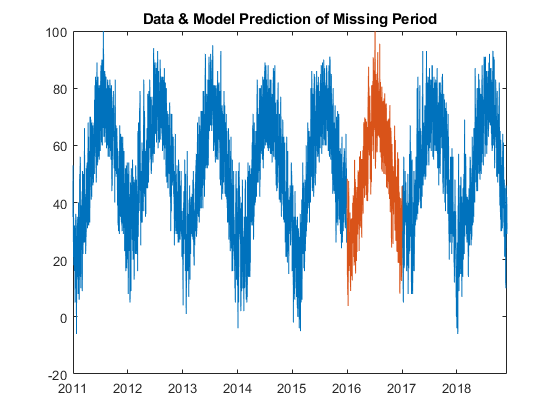

Indicies2016 = find(ismissing(T.Dry_Bulb));
preSampleNumber = tempModel.arimax.P;
preSampleIndicies = (Indicies2016(1)-preSampleNumber):Indicies2016(1)-1;
Temp2016= simulate(tempModel.arimax,length(Indicies2016),'Y0',T.Dry_Bulb(preSampleIndicies),'X',T.AveTemp(preSampleIndicies(1):Indicies2016(end)));
figure
plot(T.Date,T.Dry_Bulb, T.Date(Indicies2016), Temp2016)
title('Data & Model Prediction of Missing Period')

Now we can simulate the electricity price for 2016 and compare to the original.

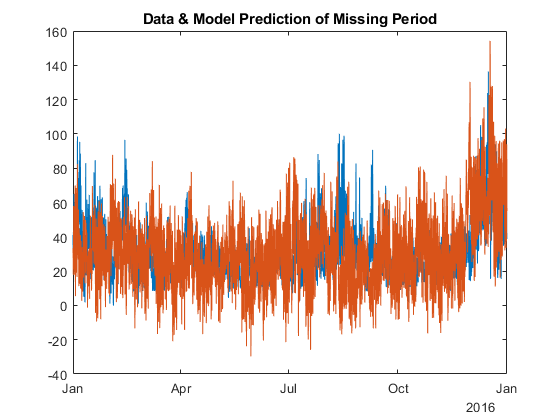

T.Dry_Bulb(Indicies2016) = Temp2016;
T.TempDeviation(Indicies2016) = Temp2016 - T.AveTemp(Indicies2016);
T.pred = trainedModel.predictFcn(timetable2table(T));
elecPrices2016= simulate(ARIMAX_ElecPrices,length(Indicies2016),'Y0',T.DA_LMP(preSampleIndicies),'X',T.pred(preSampleIndicies(1):Indicies2016(end)));
figure
plot(T.Date(Indicies2016),T.DA_LMP(Indicies2016), T.Date(Indicies2016), elecPrices2016)
title('Data & Model Prediction of Missing Period')